# Listing of Included Widgets

FAIL - Most links on this page fail from browser

## [Button Grid](matlab:open('./ButtonGridExample.html'))

The [`wt.ButtonGrid`](matlab:open('..\+wt\ButtonGrid.m')) widget provides an array of pushbutton controls that are grouped together. You provide an array of icons and/or text labels for the buttons. It has a single callback function that provides eventdata indicating which button was pushed.

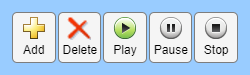

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 75]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
buttonGridWidget = wt.ButtonGrid(gridObj);
buttonGridWidget.BackgroundColor = [.6 .8 1];
buttonGridWidget.Icon = [
    "add_24.png"
    "delete_24.png"
    "play_24.png"
    "pause_24.png"
    "stop_24.png"
    ];
buttonGridWidget.Text = [
    "Add"
    "Delete"
    "Play"
    "Pause"
    "Stop"
    ];

## [Checkbox List](matlab:open('.\exampleshtml\CheckboxListExample.html'))

The [`wt.CheckboxList`](matlab:open('..\widgets+wt\CheckboxList.m')) widget provides an array of checkboxes within a scrollable panel. 

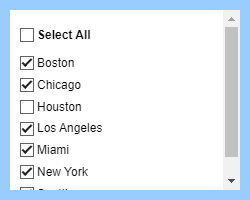

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 200]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
cbListWidget = wt.CheckboxList(gridObj);

% Configure the widget
cbListWidget.Items = [
    "Boston"
    "Chicago"
    "Houston"
    "Los Angeles"
    "Miami"
    "New York"
    "Seattle"
    ];
cbListWidget.Value(3) = false;
cbListWidget.ShowSelectAll = true;

## [Color Selector](matlab:open('.\exampleshtml\ColorSelectorExample.html'))

The [`wt.ColorSelector`](matlab:open('..\widgets+wt\ColorSelector.m')) widget enables you to have a color selection edit field along with a button that opens a color selection dialog. 

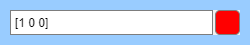

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 45]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
colorWidget = wt.ColorSelector(gridObj);
colorWidget.Value = [1 0 0];

If you are using R2024a or later, consider if the built-in [`uicolorpicker`](https://www.mathworks.com/help/matlab/ref/uicolorpicker.html) meets your needs instead.

## [Contextual View](matlab:open('.\exampleshtml\ContextualViewWidget.html'))

The [`wt.ContextualView`](matlab:open('..+wt\ContextualView.m')) widget is an advanced component that is visually like a tabpanel but without the tabs. It is intended for use in apps with a modular implementation using the [model-view-controller](https://en.wikipedia.org/wiki/Model%E2%80%93view%E2%80%93controller) (MVC) design pattern. The `ContextualView` provides a multiple-view container for recangular contents similar to a `uitabgroup. However`, unliike `uitabgroup`, the `ContextualView` provides only a programmatic interface for launching a component and placing it within the widget. 

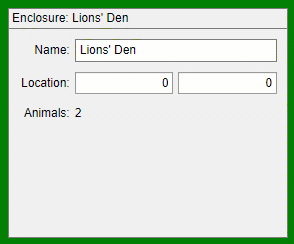

## [Datetime Selector](matlab:open('.\exampleshtml\DatetimeSelectorExample.html'))

The [`wt.DatetimeSelector`](matlab:open('..\widgets+wt\DatetimeSelector.m')) widget provides a combined date and time selection. You may optionally include seconds, time zone, and AM/PM selection. It's value uses a datetime object.

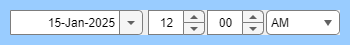

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 350 45]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
dateWidget = wt.DatetimeSelector(gridObj);

## [Drop Down List Manager](matlab:open('.\exampleshtml\DropDownListManagerExample.html'))

The [`wt.DropDownListManager`](matlab:open('..\widgets+wt\DropDownListManager.m')) widget provides the user to edit and select from a list of names, and it does so within a compact space. You can easily add, remove, or rename items from the dropdown control using the connected buttons.

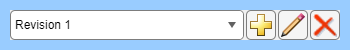

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 350 50]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);
gridObj.RowHeight = {30};

% Create the widget
ddlWidget = wt.DropDownListManager(gridObj);
ddlWidget.AllowRemove = true;
ddlWidget.AllowRename = true;
ddlWidget.Items = [
    "Initial Configuration"
    "Revision 1"
    "Revision 2"
    ];
ddlWidget.Value = "Revision 1";

## [File Selector](matlab:open('.\exampleshtml\FileSelectorExample.html'))

The [`wt.FileSelector`](matlab:open('..\widgets+wt\FileSelector.m')) widget provides a file path edit field along with a button that opens a file selection dialog. 

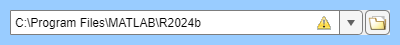

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 400 45]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
fileWidget = wt.FileSelector(gridObj);
fileWidget.Value = matlabroot;
fileWidget.ShowHistory = true;

## [List Selector (single pane)](matlab:open('.\exampleshtml\ListSelectorExample.html'))

The [`wt.ListSelector`](matlab:open('..\widgets+wt\ListSelector.m')) widget is intended for adding items to a list from a known set. You can optionally enable reordering the items, and add custom buttons.

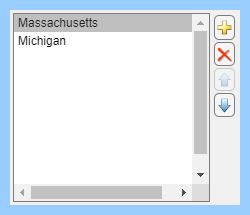

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 215]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Load data
load("usastates.mat","usastates");
stateNames = string({usastates.Name});

% Create the widget
listWidget = wt.ListSelector(gridObj);
listWidget.Items = stateNames;
listWidget.Value = ["Massachusetts","Michigan"];

## [List Selector Two Pane](matlab:open('.\exampleshtml\ListSelectorTwoPaneExample.html'))

The [`wt.ListSelectorTwoPane`](matlab:open('..\widgets+wt\ListSelectorTwoPane.m')) widget is similar to the one-pane variant. It is intended for adding items to a list from a known set. In this case, the set of available items is displayed in a list on the left side, and items are selectively added to the right list.

Again you can optionally enable reordering the items and add custom buttons.

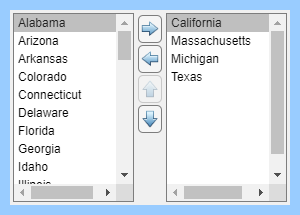

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 300 215]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Load data
load("usastates.mat","usastates");
stateNames = string({usastates.Name});

% Create the widget
listWidget2 = wt.ListSelectorTwoPane(gridObj);
listWidget2.Items = stateNames;
listWidget2.Value = ["California","Massachusetts","Michigan","Texas"];

## [Numeric Array](matlab:open('.\exampleshtml\NumericArrayExample.html'))

The [`wt.NumericArray`](matlab:open('..\widgets+wt\NumericArray.m')) widget combines multiple numeric edit fields that form elements of a 1-dimensional array. It is intended for small arrays typically 2 to 5 values. Optionally you may impose restrictions on the numerical range. You can also force the array to be `increasing` or `decreasing`. You can also set orientation as `horizontal` or `vertical`.

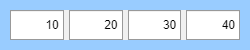

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 50]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
naWidget = wt.NumericArray(gridObj);
naWidget.Value = [10 20 30 40];

## [Password Field](matlab:open('.\exampleshtml\PasswordFieldExample.html'))

The [`wt.PasswordField`](matlab:open('..\widgets+wt\PasswordField.m')) widget provides a password field with text displayed as dots. 

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 45]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
passwordWidget = wt.PasswordField(gridObj);
passwordWidget.Value = "MathWorks";

## [Progress Bar](matlab:open('.\exampleshtml\ProgressBarExample.html'))

The [`wt.ProgressBar`](matlab:open('..\widgets+wt\ProgressBar.m')) widget provides a progress indicator that can be embedded within your app. 

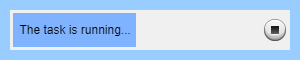

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 300 60]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
progressWidget = wt.ProgressBar(gridObj);

% Configure the widget
progressWidget.ShowCancel = true;
progressWidget.setProgress(0.5, "The task is running...");

## [Range Field](matlab:open('.\exampleshtml\RangeFieldExample.html'))

The [`wt.RangeField`](matlab:open('..\widgets+wt\RangeField.m')) widget combines multiple numeric edit fields that form elements of a 1-dimensional array. It is intended for small arrays typically 2 to 5 values. Optionally you may impose restrictions on the numerical range. You can also force the array to be `increasing` or `decreasing`. You can also set orientation as `horizontal` or `vertical`.

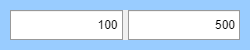

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 50]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
rfWidget = wt.RangeField(gridObj);
rfWidget.Value = [100 500];

## [Row Entries Table](matlab:open('.\exampleshtml\RowEntriesTableExample.html'))

The [`wt.RowEntriesTable`](matlab:open('..\widgets+wt\RowEntriesTable.m')) widget is intended to enable display and editing of simple lists when each item (row) has multiple attributes (columns) to configure. You can add or remove rows using the buttons. You may optionally enable ordering buttons to move items up and down the list.

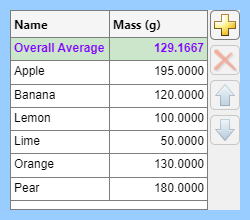

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 220]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
rtWidget = wt.RowEntriesTable(gridObj);
rtWidget.Orderable = true; % Enables the up/down buttons to reorder items
fruitData = cell2table({
    "Apple", 195
    "Banana", 120
    "Lemon", 100
    "Lime", 50
    "Orange", 130
    "Pear", 180
    }, "VariableNames", ["Name","Mass (g)"]);
meanMass = mean(fruitData.("Mass (g)"));
fruitData = [
    {"Overall Average", meanMass}
    fruitData
    ];
rtWidget.AllowItemRemove(1) = false;
rtWidget.AllowItemOrdering(1) = false;
firstRowStyle = uistyle("BackgroundColor",[.8 .9 .8],"FontWeight","bold","FontColor",[.5 0 1]);
rtWidget.addStyle(firstRowStyle, "row", 1)
pause(2); drawnow
rtWidget.Data = fruitData; drawnow

## [Slider Checkbox Combination Group](matlab:open('.\exampleshtml\SliderCheckboxExample.html'))

The [`wt.SliderCheckboxGroup`](matlab:open('..\widgets+wt\SliderCheckboxGroup.m')) widget provides a set of slider values with checkboxes that enable or disable them. This is useful for setting things like the visibilities of colors or layer transparency that varies between 0 and 1.

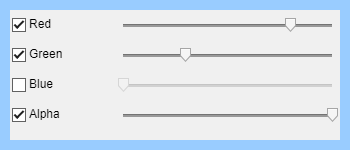

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 350 150]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
sliderCheckboxWidget = wt.SliderCheckboxGroup(gridObj);

% Configure the widget
sliderCheckboxWidget.Name = ["Red", "Green", "Blue", "Alpha"];
sliderCheckboxWidget.CheckboxWidth = 100;
sliderCheckboxWidget.Value = [0.8, 0.3, 0, 1];
sliderCheckboxWidget.State = [true, true, false, true];

## [Slider Spinner Combination](matlab:open('.\exampleshtml\SliderSpinnerExample.html'))

The [`wt.SliderSpinner`](matlab:open('..\widgets+wt\SliderSpinner.m')) widget provides a slider alongside a numeric edit field with spinner buttons. It is useful if the user needs to be able to both slide the value or enter it as text.

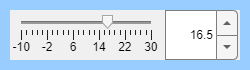

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 70]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
sliderSpinnerWidget = wt.SliderSpinner(gridObj);

% Configure the widget
sliderSpinnerWidget.Limits = [-10 30];
sliderSpinnerWidget.RoundFractionalValues = "off";
sliderSpinnerWidget.Step = 0.5;
sliderSpinnerWidget.Value = 16.5;

## [Task Status Table](matlab:open('.\exampleshtml\TaskStatusTableExample.html'))

The [`wt.TaskStatusTable`](matlab:open('..\widgets+wt\TaskStatusTable.m')) widget provides a list of process or workflow steps that should be performed in order. It enables stepping forward or back using the included buttons. You can also choose from standard status icons beside each item in the list.

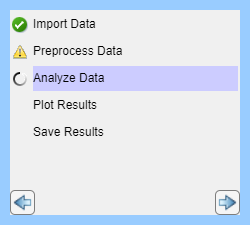

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 225]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
taskStatusWidget = wt.TaskStatusTable(gridObj);

% Configure the widget
taskStatusWidget.Items = [
    "Import Data"
    "Preprocess Data"
    "Analyze Data"
    "Plot Results"
    "Save Results"
    ];
taskStatusWidget.Status = [
    "complete"
    "warning"
    "running"
    "none"
    "none"
    ];
taskStatusWidget.SelectedIndex = 3;

## [Toolbar](matlab:open('.\exampleshtml\ToolbarExample.html'))

The [`wt.Toolbar`](matlab:open('..\widgets+wt\Toolbar.m')) widget enables you to construct a lightweight toolstrip or toolbar for controlling your app. You can add buttons with icons and text and create multiple sections. 

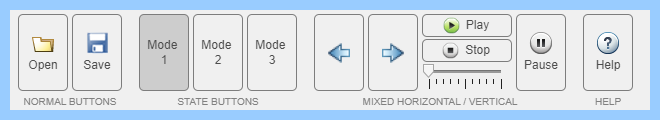

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 660 120]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
toolbarWidget1 = wt.Toolbar(gridObj);

% Create a horizontal section
section1 = wt.toolbar.HorizontalSection();
section1.Title = "NORMAL BUTTONS";
section1.addButton("open_24.png", "Open");
section1.addButton("save_24.png", "Save");

% Create a horizontal section with state buttons
section2 = wt.toolbar.HorizontalSection();
section2.Title = "STATE BUTTONS";
stateButton1 = section2.addStateButton("","Mode 1");
stateButton2 = section2.addStateButton("","Mode 2");
stateButton3 = section2.addStateButton("","Mode 3");

% Set the state of the buttons
stateButton1.Value = true;
stateButton2.Value = false;
stateButton3.Value = false;

% Create a horizontal section with vertical subsection
section3 = wt.toolbar.HorizontalSection();
section3.Title = "MIXED HORIZONTAL / VERTICAL";
section3.addButton("left_24.png","");
section3.addButton("right_24.png","");

% Create the vertical subsection
section3v1 = section3.addVerticalSection();
section3v1.addButton("play_24.png","Play");
section3v1.addButton("stop_24.png","Stop");

% Add a manual component to the  vertical section
sliderObj = uislider("Parent",[]);
section3v1.Component(end+1) = sliderObj;

% Attach a callback to the slider
% This is required for manually adding components
sliderObj.ValueChangedFcn = @(src,evt)disp(evt);

% Create more horizontal items
section3.addButton("pause_24.png","Pause");

% Add another basic section
section4 = wt.toolbar.HorizontalSection();
section4.Title = "HELP";
section4.addButton('help_24.png','Help');

% Attach the horizontal sections to the toolbar
toolbarWidget1.Section = [
    section1
    section2
    section3
    ]; 
drawnow % to get it to render the width before snapshot occurs
toolbarWidget1.Section(end+1) = section4;

*Copyright 2020-2025 The MathWorks, Inc.*